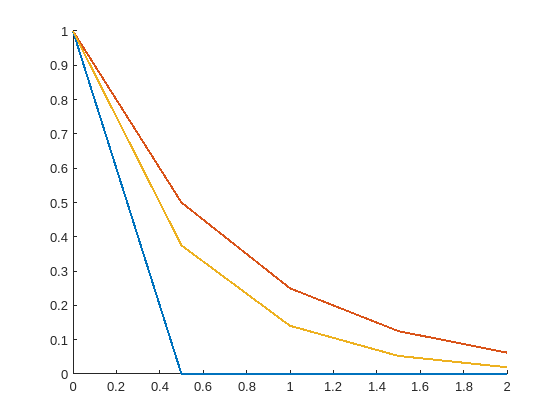

close all
lambda = -2;

dt = 0.5;

tf = 2;

x = zeros(tf/dt,1);

x(1) = 1;

RK_orders = [1 2 4];

global_error = zeros(4,3);

figure(1)
hold on
for k = 1:length(RK_orders)
    
RK_order = RK_orders(k);

switch RK_order
    case 1
        a = [0];
        b = [1];
        c = [0];
        butcher = struct('a',a,'b',b,'c',c);
    case 2
        a = [0 0; .5 0];
        b = [0 1];
        c = [0 .5];
        butcher = struct('a',a,'b',b,'c',c);
    case 4
        a = [0 0 0 0; .5 0 0 0; 0 .5 0 0; 0 0 1 0];
        b = [1/6 1/3 1/3 1/6];
        c = [0 .5 .5 1];
        butcher = struct('a',a,'b',b,'c',c);
end
f = @(x) lambda * x;

u = @(t) 0;

for i=2:tf/dt+1
   x(i) = generic_RK(butcher,x(i-1),dt,f,i*dt,u);
end

%global_error(tt,k) = abs(x(end)-xsol(2));
% Plotting

plot(0:dt:tf,x,'Linewidth',1.5)
pause(1)
end

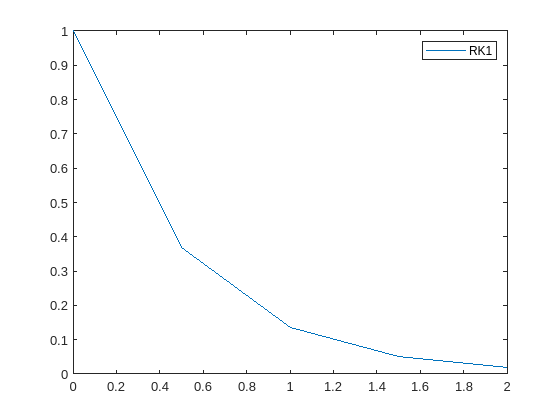


% b)

syms x(t)

ode = diff(x) == x*lambda;

xsol(t) = dsolve(ode,x(0) == 1);



t = 0:dt:tf;
figure
plot(t,(xsol(t)))

legend('RK1','RK2','RK4')

%% close all
%2b)
lambda = -2;

dts = [1 0.5 0.1 0.01 0.001];
global_error = zeros(4,3);

for tt=1:length(dts)

    dt = dts(tt);
    
    tf = 2;
    
    x = zeros(tf/dt,1);
    
    x(1) = 1;
    
    RK_orders = [1 2 4];
    
    
    for k = 1:length(RK_orders)
    
        RK_order = RK_orders(k);
        
        switch RK_order
            case 1
                a = [0];
                b = [1];
                c = [0];
                butcher = struct('a',a,'b',b,'c',c);
            case 2
                a = [0 0; .5 0];
                b = [0 1];
                c = [0 .5];
                butcher = struct('a',a,'b',b,'c',c);
            case 4
                a = [0 0 0 0; .5 0 0 0; 0 .5 0 0; 0 0 1 0];
                b = [1/6 1/3 1/3 1/6];
                c = [0 .5 .5 1];
                butcher = struct('a',a,'b',b,'c',c);
        end
        f = @(x) lambda * x;
        
        u = @(t) 0;
        
        for i=2:tf/dt+1
           x(i) = generic_RK(butcher,x(i-1),dt,f,i*dt,u);
        end
        
        global_error(tt,k) = abs(x(end)-xsol(tf));
        
    end
end

% b)

% Plotting
global_error(:,1)

ans =     0.9817
    0.0183
    0.0068
    0.0007
    0.0001


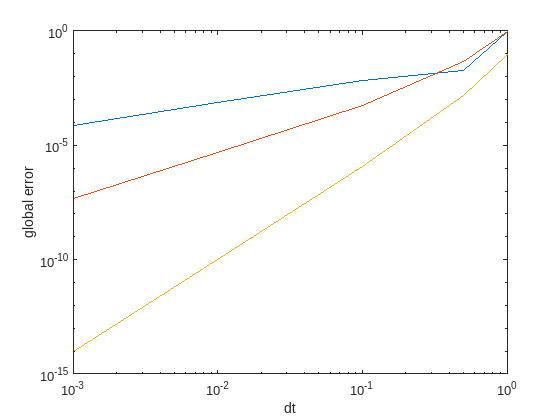

loglog(dts,global_error(:,1),dts,global_error(:,2),dts,global_error(:,3))
xlabel('dt')
ylabel('global error')

% legend('RK1','RK2','RK4')

%% 2c)
clear lambda
syms lambda
lam=0;
for k = 1:length(RK_orders)
    sum=1; 
    for i=1:RK_orders(k)   
        sum = sum + ((lambda*dt)^i/factorial(i));
    end
    sum=abs(sum);
    lam = double(solve(sum==1, lambda<0));
end

% 
% %% 3
% clear t
% 
% tspan = [0 25];
% 
% x0 = [1 0];
% 
% f = @(t, x) [x(2);
%              5*(1-x(1)^2)*x(2)-x(1)];
% 
% y = ode45(f, tspan, x0);
% 
% plot(y.x,y.y(1,:),'--','Linewidth',1.5)
% hold on
% plot(y.x,y.y(2,:),'--','Linewidth',1.5)
% 
% 
% % RK4
% 
% dt = 0.125;
% tf = 25;
% t = 0:dt:tf;
% 
% x = zeros(tf/dt,2);
% x(1,:) = [1 0];
% 
% u = @(t) 0;
% 
% a = [0 0 0 0; .5 0 0 0; 0 .5 0 0; 0 0 1 0];
% b = [1/6 1/3 1/3 1/6];
% c = [0 .5 .5 1];
% 
% butcher = struct('a',a,'b',b,'c',c);
% 
% f = @(x,u) [x(2);
%             5*(1-x(1)^2)*x(2)-x(1)];
% 
% for i=2:tf/dt+1
%    x(i,:) = generic_RK(butcher,x(i-1,:),dt,f,i*dt,u);
% end
% 
% plot(t,x(:,1))
% hold on
% plot(t,x(:,2))
